## Φόρτωση εικόνας


clear; close all; clc;

load(fullfile('Images','Ασκηση 3','tiger.mat'));   % μεταβλητή: tiger
img = im2double(tiger);                            % [0,1]

% Βασικές συναρτήσεις βοηθητικές
snr_db_to_noisevar = @(signal, SNRdB) mean(signal(:).^2) / 10^(SNRdB/10);
psnr_val = @(A,B) psnr(A,B);
ssim_val = @(A,B) ssim(A,B);
h_avg = fspecial('average',[3 3]);   



## 3.1 Λευκός Gaussian θόρυβος – Moving Average & Median



disp('--------------- 3.1 Gaussian 15 dB ---------------');

--------------- 3.1 Gaussian 15 dB ---------------


sigma2 = snr_db_to_noisevar(img,15);
gauss_noise = sqrt(sigma2) .* randn(size(img));
img_gauss = min(max(img + gauss_noise,0),1);

img_avg_31 = imfilter(img_gauss, h_avg, 'replicate');
img_med_31 = medfilt2(img_gauss,[3 3],'symmetric');

psnr_gauss = psnr_val(img_gauss,img);
psnr_avg31 = psnr_val(img_avg_31,img);
psnr_med31 = psnr_val(img_med_31,img);

fprintf('\n3.1 PSNR Gaussian: %.2f dB\n', psnr_gauss);


3.1 PSNR Gaussian: 22.73 dB


fprintf('3.1 PSNR Moving Average: %.2f dB\n', psnr_avg31);

3.1 PSNR Moving Average: 21.78 dB


fprintf('3.1 PSNR Median: %.2f dB\n', psnr_med31);

3.1 PSNR Median: 22.35 dB


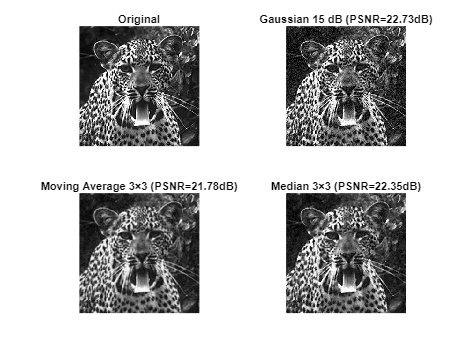


figure('Name','3.1 Gaussian 15 dB','NumberTitle','off');
subplot(2,2,1), imshow(img), title('Original');
subplot(2,2,2), imshow(img_gauss), title(sprintf('Gaussian 15 dB (PSNR=%.2fdB)', psnr_gauss));
subplot(2,2,3), imshow(img_avg_31), title(sprintf('Moving Average 3×3 (PSNR=%.2fdB)', psnr_avg31));
subplot(2,2,4), imshow(img_med_31), title(sprintf('Median 3×3 (PSNR=%.2fdB)', psnr_med31));

## 3.2 Κρουστικός θόρυβος (Salt & Pepper 20 %) – Moving Average & Median


disp('--------------- 3.2 Salt & Pepper 20 % ---------------');

--------------- 3.2 Salt & Pepper 20 % ---------------


img_sp = imnoise(img,'salt & pepper',0.20);

img_avg_32 = imfilter(img_sp, h_avg, 'replicate');
img_med_32 = medfilt2(img_sp,[3 3],'symmetric');

psnr_sp = psnr_val(img_sp,img);
psnr_avg32 = psnr_val(img_avg_32,img);
psnr_med32 = psnr_val(img_med_32,img);

fprintf('\n3.2 PSNR Salt & Pepper: %.2f dB\n', psnr_sp);


3.2 PSNR Salt & Pepper: 11.58 dB


fprintf('3.2 PSNR Moving Average: %.2f dB\n', psnr_avg32);

3.2 PSNR Moving Average: 17.30 dB


fprintf('3.2 PSNR Median: %.2f dB\n', psnr_med32);

3.2 PSNR Median: 20.58 dB


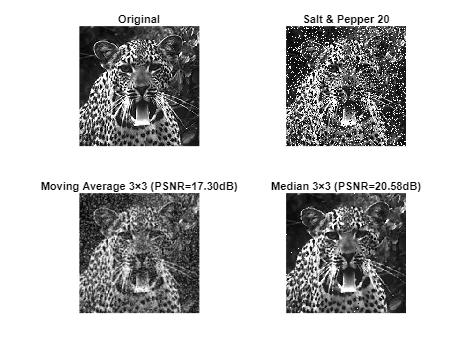


figure('Name','3.2 Salt & Pepper 20%','NumberTitle','off');
subplot(2,2,1), imshow(img), title('Original');
subplot(2,2,2), imshow(img_sp), title(sprintf('Salt & Pepper 20% (PSNR=%.2fdB)', psnr_sp));
subplot(2,2,3), imshow(img_avg_32), title(sprintf('Moving Average 3×3 (PSNR=%.2fdB)', psnr_avg32));
subplot(2,2,4), imshow(img_med_32), title(sprintf('Median 3×3 (PSNR=%.2fdB)', psnr_med32));

## 3.3 Συνδυασμένος θόρυβος – Σειριακή εφαρμογή φίλτρων


disp('--------------- 3.3 Συνδυασμένος θόρυβος ---------------');

--------------- 3.3 Συνδυασμένος θόρυβος ---------------


sigma2 = snr_db_to_noisevar(img,15);
gauss_noise = sqrt(sigma2) .* randn(size(img));
img_combo = min(max(img + gauss_noise,0),1);
img_combo = imnoise(img_combo,'salt & pepper',0.20);

tmp_a = imfilter(img_combo, h_avg, 'replicate');
img_a = medfilt2(tmp_a, [3 3],'symmetric');

tmp_b = medfilt2(img_combo, [3 3],'symmetric');
img_b = imfilter(tmp_b, h_avg, 'replicate');

psnr_combo = psnr_val(img_combo,img);
psnr_a = psnr_val(img_a,img);
psnr_b = psnr_val(img_b,img);

fprintf('\n3.3 PSNR Συνδυασμένος θόρυβος: %.2f dB\n', psnr_combo);


3.3 PSNR Συνδυασμένος θόρυβος: 11.41 dB


fprintf('3.3 (α) MA→Median PSNR: %.2f dB\n', psnr_a);

3.3 (α) MA→Median PSNR: 17.09 dB


fprintf('3.3 (β) Median→MA PSNR: %.2f dB\n', psnr_b);

3.3 (β) Median→MA PSNR: 19.36 dB


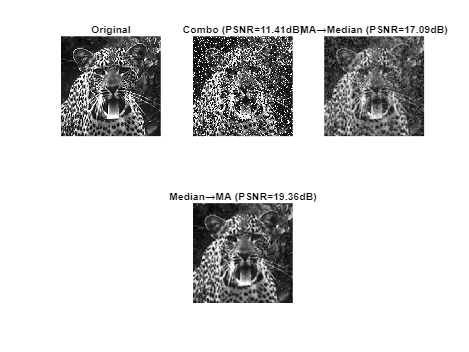


figure('Name','3.3 Συνδυασμένος θόρυβος','NumberTitle','off');
subplot(2,3,1), imshow(img), title('Original');
subplot(2,3,2), imshow(img_combo), title(sprintf('Combo (PSNR=%.2fdB)', psnr_combo));
subplot(2,3,3), imshow(img_a), title(sprintf('MA→Median (PSNR=%.2fdB)', psnr_a));
subplot(2,3,5), imshow(img_b), title(sprintf('Median→MA (PSNR=%.2fdB)', psnr_b));